## **Bayesian Optimisation Example**

Goal: *maximise the function f(x) = x.*sin( x );  in the interval [0, 10]*

clear
close all
x = linspace( 0, 10, 501 ).';
f = x.*sin( x );


Extract 7 points for training an initial surrogate model & plot the results:

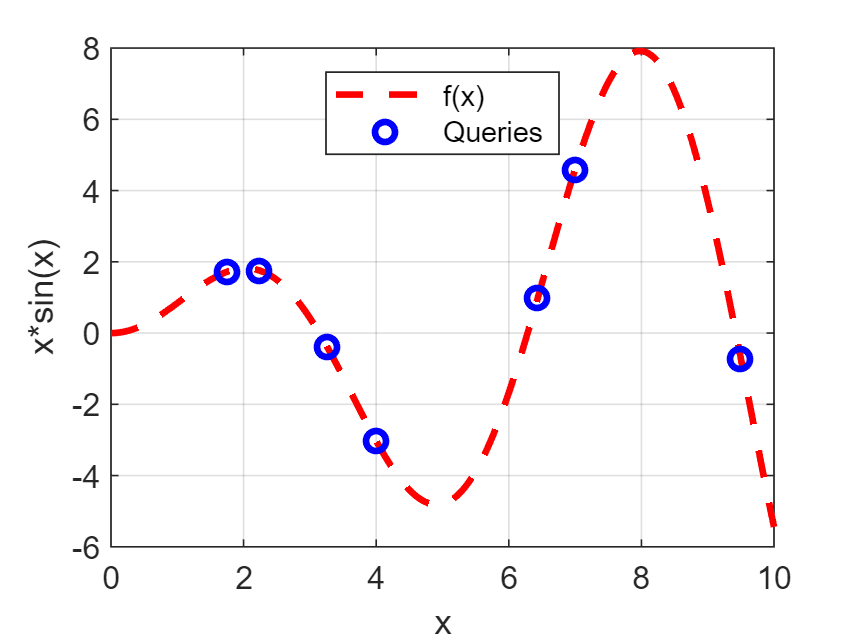

X = [ 9.5, 2.24, 4, 1.76, 3.26, 6.44, 7.0 ].';
Y = X .* sin( X );
plot( x, f, 'r--', X, Y, 'bo', 'LineWidth', 2 );
grid on
xlabel( "x" );
ylabel( "x*sin(x)" );
legend( "f(x)", "Queries", "Location", "north")

Create the Bayesian Optimisation object. Assume a Gaussian Process Regression model and the Upper Confidence Bound acquisition function

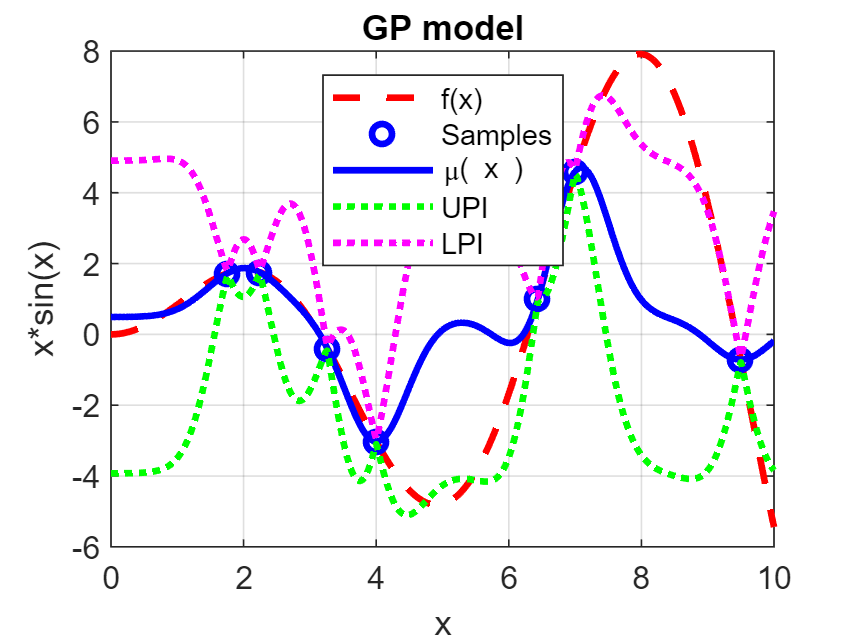

B = bayesOpt();
B = B.setTrainingData( X, Y );
[ Yp, ~, Yint] = B.predict( x, 0.05 );
close all
figure;
plot(x, f, 'r--', X, Y, 'bo', x, Yp, 'b-', 'LineWidth', 2);
grid on
legend( "f(x)", "Samples", "\mu( x )", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");
hold on;
plot(  x, Yint( :,1 ), 'g:', x, Yint( :,2 ), 'm:', 'LineWidth', 2);
legend( "f(x)", "Samples", "\mu( x )", "UPI", "LPI", 'Location', 'north');

Mminimise -UCB(x)

B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -4.613334e+00    0.000e+00    2.420e+00
    1       7   -4.695801e+00    0.000e+00    2.899e+00    3.026e-01
    2       9   -4.903637e+00    0.000e+00    5.651e-01    1.649e-01
    3      11   -4.910310e+00    0.000e+00    6.653e-02    2.690e-02
    4      13   -4.910405e+00    0.000e+00    7.082e-04    2.833e-03
    5      15   -4.910405e+00    0.000e+00    1.015e-06    3.048e-05
    6      17   -4.910405e+00    0.000e+00    1.665e-08    4.364e-08

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the 

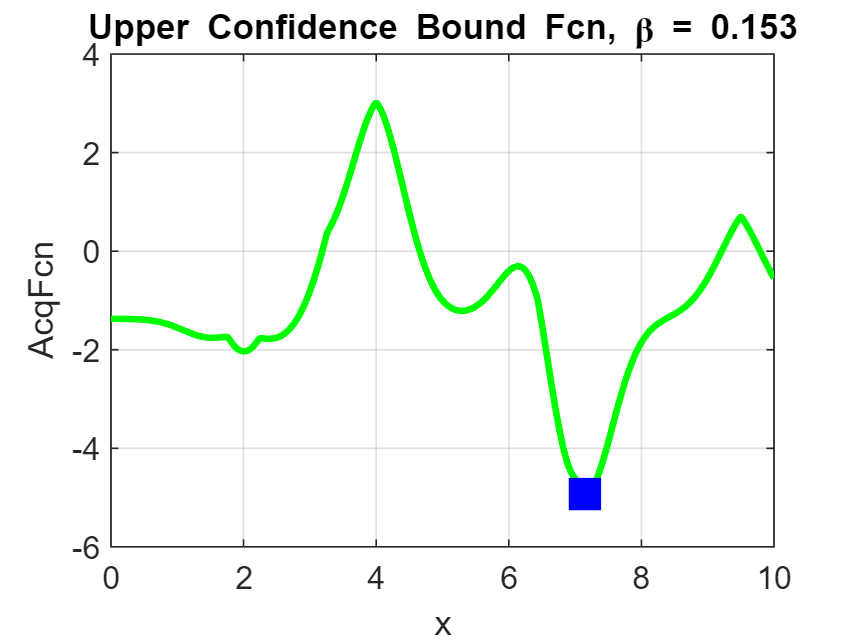

U = B.AcqObj;
figure;
A = U.evalFcn( x, U.Beta );
plot( x, A, 'g-', 'LineWidth', 2); grid on
xlabel( "x" )
ylabel( "AcqFcn" )
Tstr = sprintf( "Upper Confidence Bound Fcn, \\beta = %4.3f", U.Beta );
title( Tstr ); 
hold on, plot( B.Xnext, B.AcqObj.evalFcn( B.Xnext ), "bs", "MarkerSize", 12, "MarkerFaceColor", "blue" );
grid on
hold off

Query f(x) at the suggested value and update the GP model

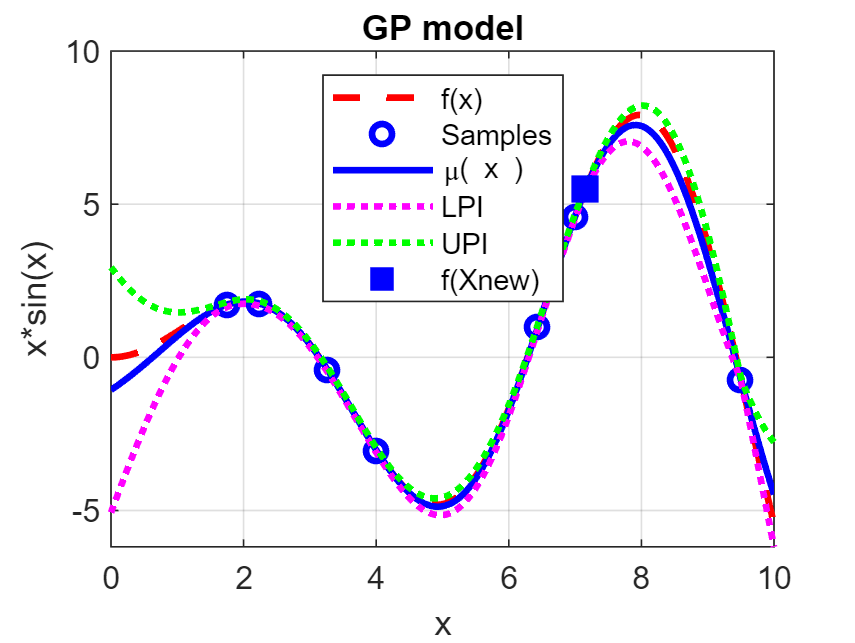

figure;
Xnew = B.Xnext;
Ynew = Xnew * sin( Xnew );
B = B.addNewQuery( Xnew, Ynew );
[ Yp, ~, Yint ] = B.predict( x );
plot(x, f, 'r--', X, Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");

Now re-optimise the acquisition function

B = B.acqFcnMaxTemplate();

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       2   -5.516712e+00    0.000e+00    5.182e+00
    1       6   -6.584197e+00    0.000e+00    4.199e+00    1.295e+00
    2       8   -7.690024e+00    0.000e+00    4.498e-01    5.799e-01
    3      10   -7.702515e+00    0.000e+00    5.360e-03    5.611e-02
    4      12   -7.702517e+00    0.000e+00    2.675e-05    6.607e-04
    5      14   -7.702517e+00    0.000e+00    1.488e-06    3.281e-06
    6      16   -7.702517e+00    0.000e+00    1.600e-06    1.932e-07
    7      18   -7.702517e+00    0.000e+00    6.462e-07    1.001e-07

Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the va

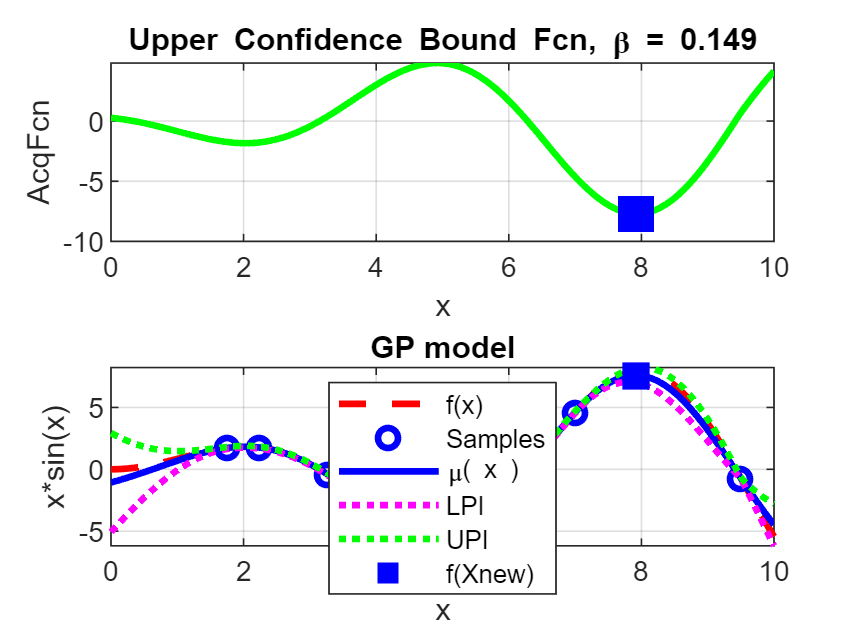

figure;
Xnew = B.Xnext;
subplot(2,1,1), plot( x, B.AcqObj.evalFcn( x ), 'g-', Xnew, B.AcqObj.evalFcn( Xnew ), 'bs', 'MarkerSize', 12,'LineWidth', 2, 'MarkerFaceColor','blue');
grid on
xlabel( "x" )
ylabel( "AcqFcn" )
Tstr = sprintf( "Upper Confidence Bound Fcn, \\beta = %4.3f", U.Beta );
title( Tstr ); 
subplot(2,1,2)
Xnew = B.Xnext;
Ynew = B.predict( Xnew );
B = B.addNewQuery( Xnew, Ynew );
plot(x, f, 'r--', X, Y, 'bo', x, Yp, 'b-', x, Yint( :,1 ), 'm:',...
    x, Yint( :,2 ), 'g:',  'LineWidth', 2);
hold on
plot( Xnew, Ynew, 'bs', 'MarkerSize', 10, 'MarkerFaceColor', 'blue');
grid on
legend( "f(x)", "Samples", "\mu( x )", "LPI", "UPI", "f(Xnew)", 'Location', 'north');
xlabel( "x" );
ylabel( "x*sin(x)" );
title( "GP model");